# Multiplet

## Accès dossier et choix essai

Il est nécessaire d'avoir lancé "Correlation.mat" précédement

clear ;
Type = 'DPMS0T';
Materiau = '7075';
Eprouvette ='3';
Numero = '1';
 ;
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

## Sélection WF pour multiplets

 ;
seuil =0.9;
Nbre = 1;

HDD = sortrows(HDD,'Time'); 

% Comptage du nombre de waveforms par channel
channel = HDD.CH;
ch1Nbre = 0;
for i = 1:size(channel)
    if channel(i) == 1
        ch1Nbre = ch1Nbre + 1;
    end
end
ch2Nbre = size(channel,1)-ch1Nbre;

% Channel 1
Ext1 = [];
k = 0;
% Extraction : recherche de corrélations supérieures au seuil
for i = 1:ch1Nbre
    for j =(i+1):ch1Nbre
        if Cor1(i,j)>seuil
            k = k+1;
            Ext1(k,1) = i;
            Ext1(k,2) = j;
        end
    end
end

% Constition des multiplets
n = size(Ext1);
Nmulti = 1;
PositionMul = 0;
Mul1 = [Ext1(1,1) Ext1(1,2)];
for i = 2:n(1)
    
    % Recherche d'un multi contenant Ext1(i,1)
    [rowA,colA] = find(Mul1==Ext1(i,1));
    [rowB,colB] = find(Mul1==Ext1(i,2));
    % Création nouveau multi ou positionnement sur celui existe de Ext1(i,1)
    if isempty(rowA) == 1
        if isempty(rowB) == 1
            Nmulti = Nmulti+1;
            PositionMul = Nmulti;
            Mul1(PositionMul,1) = Ext1(i,1);
            Mul1(PositionMul,2) = Ext1(i,2);
        else
            PositionMul = rowB;
            X = find(Mul1(PositionMul,:)==0);
            if isempty(X) == 1
                Mul1(PositionMul,end+1) = Ext1(i,1);
            else
                Mul1(PositionMul,X(1)) = Ext1(i,1);
            end
        end         
    else
        if isempty(rowB) == 1
            PositionMul = rowA;
            X = find(Mul1(PositionMul,:)==0);
            if isempty(X) == 1
                Mul1(PositionMul,end+1) = Ext1(i,2);
            else
                Mul1(PositionMul,X(1)) = Ext1(i,2);
            end 
            
        else
            if rowA(1) ~= rowB(1)
                len0A = size(find(Mul1(rowA,:)==0));
                lenxB = size(find(Mul1(rowB,:)~=0));
                for a = (len0A(2)+1):lenxB(2)
                    Mul1(rowA,end+1) = 0;
                end
                xA = find(Mul1(rowA,:)==0);
                for x = 1:lenxB(2)
                    Mul1(rowA,xA(x)) = Mul1(rowB,x);
                end
                Mul1(rowB,:) = [];
            end
        end 
    end 
end

% Suppression des zeros et trie croissant des multiplets
len1 = size(Mul1);
for i = 1:len1(1)
    Multi1{i} = Mul1(i,:);
    idx = Multi1{i}==0;
    Multi1{i}(idx) = []; 
    Multi1{i} = sort(Multi1{i});
end
len1 = size(Multi1);
for i = len1(2):-1:1
    l = size(Multi1{i});
    if l(2)<Nbre
        Multi1(i) = [];
    end
end

%----------------------------------------- Channel 2
Ext2 = [];

k = 0;
% Extraction : recherche de corrélations supérieures au seuil
for i = 1:ch2Nbre
    for j =(i+1):ch2Nbre
        if Cor2(i,j)>seuil
            k = k+1;
            Ext2(k,1) = i;
            Ext2(k,2) = j;
        end
    end
end

% Constition des multiplets
n = size(Ext2);
Nmulti = 1;
PositionMul = 0;
Mul2 = [Ext2(1,1) Ext2(1,2)];
for i = 2:n(1)
    
    % Recherche d'un multi contenant Ext2(i,1)
    [rowA,colA] = find(Mul2==Ext2(i,1));
    [rowB,colB] = find(Mul2==Ext2(i,2));
    % Création nouveau multi ou positionnement sur celui qui existe de Ext1(i,1)
    if isempty(rowA) == 1
        if isempty(rowB) == 1
            Nmulti = Nmulti+1;
            PositionMul = Nmulti;
            Mul2(PositionMul,1) = Ext2(i,1);
            Mul2(PositionMul,2) = Ext2(i,2);
        else
            PositionMul = rowB;
            X = find(Mul2(PositionMul,:)==0);
            if isempty(X) == 1
                Mul2(PositionMul,end+1) = Ext2(i,1);
            else
                Mul2(PositionMul,X(1)) = Ext2(i,1);
            end
        end         
    else
        if isempty(rowB) == 1
            PositionMul = rowA;
            X = find(Mul2(PositionMul,:)==0);
            if isempty(X) == 1
                Mul2(PositionMul,end+1) = Ext2(i,2);
            else
                Mul2(PositionMul,X(1)) = Ext2(i,2);
            end 
            
        else
            if rowA(1) ~= rowB(1)
                len0A = size(find(Mul2(rowA,:)==0));
                lenxB = size(find(Mul2(rowB,:)~=0));
                for a = (len0A(2)+1):lenxB(2)
                    Mul2(rowA,end+1) = 0;
                end
                xA = find(Mul2(rowA,:)==0);
                for x = 1:lenxB(2)
                    Mul2(rowA,xA(x)) = Mul2(rowB,x);
                end
                Mul2(rowB,:) = [];
            end
        end 
    end 
end

% Suppression des zeros et trie croissant des multiplets
len2 = size(Mul2);
for i = 1:len2(1)
    Multi2{i} = Mul2(i,:);
    idx = Multi2{i}==0;
    Multi2{i}(idx) = []; 
    Multi2{i} = sort(Multi2{i});
end
len2 = size(Multi2);
for i = len2(2):-1:1
    l = size(Multi2{i});
    if l(2)<Nbre
        Multi2(i) = [];
    end
end

% Calculs et affichage de stat sur les multiplets des 2 ch
len1 = size(Multi1);
len2 = size(Multi2);
M1 = table('Size',[len1(2) 5],'VariableTypes',["double","double","double","double","double"],'VariableNames',{'Nombre_WF','Charge_moyenne','Ecart_type_charge','Nombre_cycles','ecart_type_cycle'});
M2 = table('Size',[len2(2) 5],'VariableTypes',["double","double","double","double","double"],'VariableNames',{'Nombre_WF','Charge_moyenne','Ecart_type_charge','Nombre_cycles','ecart_type_cycle'});

for i = 1:len1(2)
    l = length(Multi1{i});
    Charge = zeros(1,l);
    Num_cycles = zeros(1,l);
    % Constitution listes de charge et cycle correspondant à chaque WF d'un multi
    for j = 1:l
        idx = find(HDD.HDDWF==strcat(string(1),'_',string(Multi1{i}(j))));
        Charge(j) = HDD.PARA1(idx);
        Num_cycles(j) = fix(HDD.CYCLES(idx));
    end
    % Calculs moyennes et écarts types sur ces listes, remplissage table
    M1.Nombre_WF(i) = l;
    M1.Charge_moyenne(i) = mean(Charge);
    M1.Ecart_type_charge(i) = std(Charge);
    M1.Nombre_cycles(i) = max(Num_cycles)-min(Num_cycles);
    Num_cycles = Num_cycles(2:end)-Num_cycles(1:(end-1));
    M1.ecart_type_cycle(i) = std(Num_cycles);
end

Unable to perform assignment because the left and right sides have a different number of elements.


for i = 1:len2(2)
    l = length(Multi2{i});
    Charge = zeros(1,l);
    Num_cycles = zeros(1,l);
    % Constitution listes de charge et cycle correspondant à chaque WF d'un multi
    for j = 1:l
        idx = find(HDD.HDDWF==strcat(string(2),'_',string(Multi2{i}(j))));
        Charge(j) = HDD.PARA1(idx);
        Num_cycles(j) = fix(HDD.CYCLES(idx));
    end
    % Calculs moyennes et écarts types sur ces listes, remplissage table
    M2.Nombre_WF(i) = l;
    M2.Charge_moyenne(i) = mean(Charge);
    M2.Ecart_type_charge(i) = std(Charge);
    M2.Nombre_cycles(i) = max(Num_cycles)-min(Num_cycles);
    Num_cycles = Num_cycles(2:end)-Num_cycles(1:(end-1));
    M2.ecart_type_cycle(i) = std(Num_cycles);
end
Statistiques_multiplets_channel1 = M1
Statistiques_multiplets_channel2 = M2

## Contraintes au sein d'un multiplet

 ;

Choix des variables :

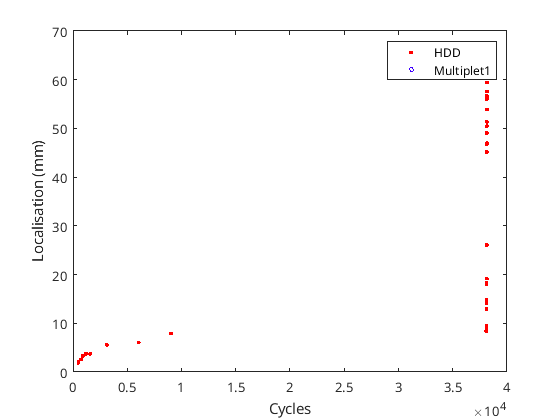

ParaX = "CYCLES";
ParaY = "LOC";
Channel = 1;

figure();
plot(HDD.(ParaX),HDD.(ParaY),'r.');
hold on   
xlabel(HDD.Properties.VariableDescriptions{ParaX});
ylabel(HDD.Properties.VariableDescriptions{ParaY});
labels = {'HDD'};
if Channel == 1
    len1 = size(Multi1); 
    for i = 1:len1(2)
        l = size(Multi1{i});
        for j = 1:l(2)
            plot(HDD.(ParaX)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi1{i}(j)))),HDD.(ParaY)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi1{i}(j)))),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)],'DisplayName',strcat('Multiplet',' ',string(i)));
        end
        labels = [labels strcat('Multiplet',' ',string(i))];
        legend(labels);
    end
else
    len2 = size(Multi2); 
    for i = 1:len2(2)
        l = size(Multi2{i});
        for j = 1:l(2)
            plot(HDD.(ParaX)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi2{i}(j)))),HDD.(ParaY)(HDD.HDDWF==strcat(string(Channel),'_',string(Multi2{i}(j)))),'o',"MarkerSize",i*3,"Color",[(0.5-i*1/(len2(2)))^2 (1-i*1/len2(2)) i*1/len2(2)],'DisplayName',strcat('Multiplet',' ',string(i)));
        end
        labels = [labels strcat('Multiplet',' ',string(i))];
        legend(labels);
    end
end
hold off
legend(labels);

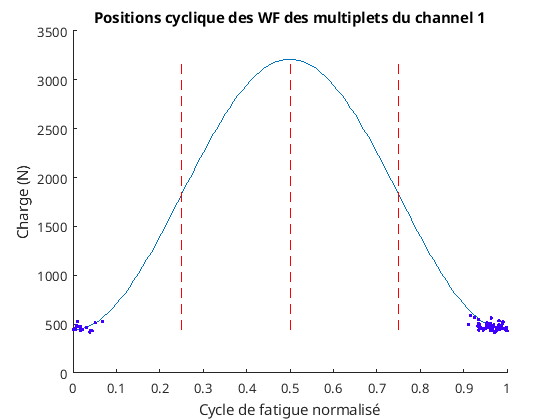


% Partie affichage de la position cyclique 
dte = mean(Cycle(2:end,2)-Cycle(1:(end-1),2));
[x0, maxi, mini] = depart_cycle(TDD,1/dte);
% maxi = maxi*1e3;
% mini = mini*1e3;

moy = (maxi+mini)/2;
Dcharge = maxi-moy;
x = (0:0.01:1);
c = [mini maxi];
figure();
hold on; 
plot(x,Dcharge*sin(2*pi*x+6*pi/4)+moy);
plot([0.5 0.5],c,'r--');
plot([0.25 0.25],c,'r--');
plot([0.75 0.75],c,'r--');
ylabel('Charge (N)');
xlabel("Cycle de fatigue normalisé");
title(strcat("Positions cyclique des WF des multiplets du channel ",string(Channel)));
labels = {'Cycle de fatigue',"Limite charge moy",'Limite charge max','Limite décharge moy'};
if Channel == 1
    len1 = size(Multi1); 
    for i = 1:len1(2)
        l = size(Multi1{i});
        for j = l(2):-1:1
            Cy = (HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi1{i}(j)))))-fix(HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi1{i}(j)))));
            plot(Cy,HDD.PARA1(HDD.HDDWF==strcat(string(Channel),'_',string(Multi1{i}(j)))),'.',"MarkerSize",(i*5),"MarkerEdgeColor",[(0.5-i*1/(len1(2)))^2 (1-i*1/len1(2)) i*1/len1(2)],'DisplayName',strcat('Multiplet',' ',string(i)));
        end
        labels = [labels strcat('Multiplet',' ',string(i))];
    end
else
    len2 = size(Multi2); 
    for i = 1:len2(2)
        l = size(Multi2{i});
        for j = l(2):-1:1
            Cy = (HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi2{i}(j)))))-fix(HDD.CYCLES(HDD.HDDWF==strcat(string(Channel),'_',string(Multi2{i}(j)))));
            plot(Cy,HDD.PARA1(HDD.HDDWF==strcat(string(Channel),'_',string(Multi2{i}(j)))),'.',"MarkerSize",(i*5),"MarkerEdgeColor",[(0.5-i*1/(len2(2)))^2 (1-i*1/len2(2)) i*1/len2(2)],'DisplayName',strcat('Multiplet',' ',string(i)));
        end
        labels = [labels strcat('Multiplet',' ',string(i))];
    end
end

## Affichage des multiplets

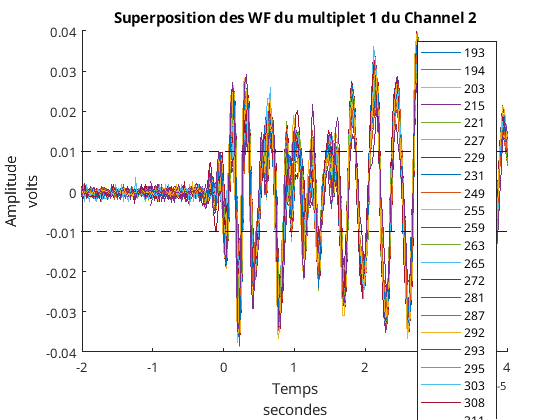

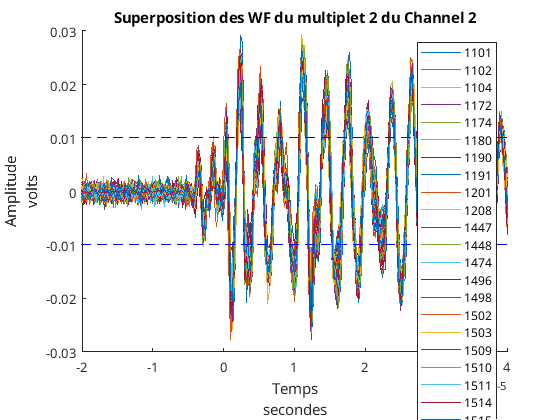

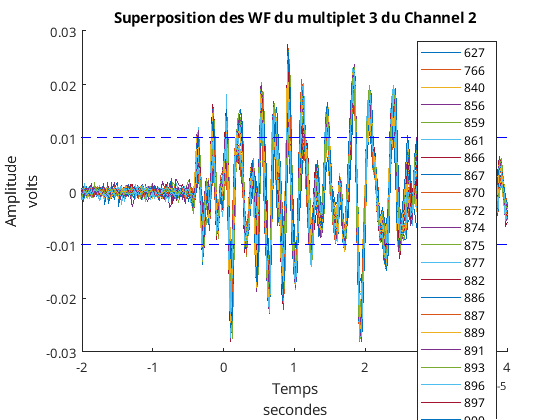

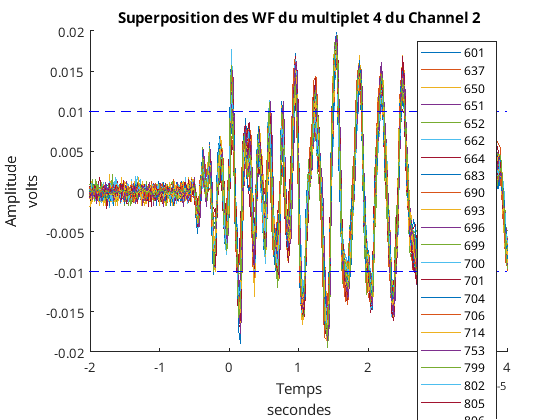

 ;
Ampl = true;
Affi = false;
fenetre = 40*1e-6;
Affiseuil = true;
thrdB =40;

if Channel == 2
    len2 = size(Multi2);
    for i = 1:len2(2)
        figure();
        hold on
        l = size(Multi2{i});
        labels = {};
        for j = 1:l(2)
            if Ampl == 1
                G = (10^((HDD.AMP(HDD.HDDWF==strcat('2_',string(Multi2{i}(1))))+40)/20)*1e-6)/(10^((HDD.AMP(HDD.HDDWF==strcat('2_',string(Multi2{i}(j))))+40)/20)*1e-6);
                plot(WF.Temps+dt2(Multi2{i}(1),Multi2{i}(j))/(5e6),G*WF.(strcat('2_',string(Multi2{i}(j)))));            
            else
                plot(WF.Temps+dt2(Multi2{i}(1),Multi2{i}(j))/(5e6),WF.(strcat('2_',string(Multi2{i}(j)))));
            end
            labels = [labels string(Multi2{i}(j))];
        end
        if Affiseuil == 1
            thr = zeros(size(WF.Temps))+10^((thrdB+40)/20)*1e-6;
            plot(WF.Temps,thr,'b--');
            plot(WF.Temps,-thr,'b--');
        end
        hold off
        xlabel({'Temps';'secondes'});
        ylabel({'Amplitude';'volts'});
        title(strcat("Superposition des WF du multiplet ",string(i),' du Channel 2'));
        if pretrig == 1
            if Affi == 1
                xlim([0 (impul-156)/(5e6)]);                                                
            else
                xlim([0 fenetre]);
            end    
        else
            if Affi == 1
                xlim([-2e-05 (impul-156)/(5e6)]);                                                
            else
                xlim([-2e-5 fenetre]);
            end
            
        end
        legend(labels)
    end
else
    len1 = size(Multi1);
    for i = 1:len1(2)
        figure();
        hold on
        l = size(Multi1{i});
        labels = {};
        for j = 1:l(2)
            if Ampl == 1
                G = (10^((HDD.AMP(HDD.HDDWF==strcat('1_',string(Multi1{i}(1))))+40)/20)*1e-6)/(10^((HDD.AMP(HDD.HDDWF==strcat('1_',string(Multi1{i}(j))))+40)/20)*1e-6);
                plot(WF.Temps+dt1(Multi1{i}(1),Multi1{i}(j))/(5e6),G.*WF.(strcat('1_',string(Multi1{i}(j)))));            
            else
                plot(WF.Temps+dt1(Multi1{i}(1),Multi1{i}(j))/(5e6),WF.(strcat('1_',string(Multi1{i}(j)))));
            end
            labels = [labels string(Multi1{i}(j))];
        end
        if Affiseuil == 1
            thr = zeros(size(WF.Temps))+10^((thrdB+40)/20)*1e-6;
            plot(WF.Temps,thr,'b--');
            plot(WF.Temps,-thr,'b--');
        end
        hold off
        xlabel({'Temps';'secondes'});
        ylabel({'Amplitude';'volts'});
        title(strcat("Superposition des WF du multiplet ",string(i),' du Channel 1'));
        if pretrig == 1
            if Affi == 1
                xlim([0 (impul-156)/(5e6)]);                                                
            else
                xlim([0 fenetre]);
            end    
        else
            if Affi == 1
                xlim([-1e-05 (impul-156)/(5e6)]);                                                
            else
                xlim([-1e-5 fenetre]);
            end
            
        end
        legend(labels)
    end
end